# PID

%% Pitch angle and position Loop PID Tuning
clc; clear; close all;

%% Parameters
m = 1.5; Cv = 0.1; Cw = 0.01; Jy = 3e-2; g = 9.81;
Ts = 0.0005;   % 5 ms

s = tf('s');

% Plants
G_inner_c = 1/(Jy*s + Cw);     % M -> w
G_inner   = c2d(G_inner_c, Ts, 'zoh');

G_phi     = c2d(1/s, Ts, 'tustin');   % w -> phi
G_vphi    = c2d(g/s, Ts, 'tustin');   % phi -> v (small-angle approx)
G_x       = c2d(1/s, Ts, 'tustin');   % v -> x

%% Tunable PIDs
C_rate  = tunablePID('C_rate','PID');  C_rate.Ts = Ts;
C_angle = tunablePID('C_angle','PID'); C_angle.Ts = Ts;
C_vel   = tunablePID('C_vel','PID');     C_vel.Ts  = Ts;
C_pos   = tunablePID('C_pos','P');      C_pos.Ts  = Ts;

% Constraints
C_rate.Kp.Minimum = 0;  C_rate.Ki.Minimum = 0;  C_rate.Kd.Minimum = 0; C_rate.Tf.Minimum=1; C_rate.Tf.Maximum=1000;
C_angle.Kp.Minimum = 0;  C_angle.Ki.Minimum = 0;  C_angle.Kd.Minimum = 0; C_angle.Tf.Minimum=1; C_angle.Tf.Maximum=1000;
C_vel.Kp.Minimum = 0;  C_vel.Ki.Minimum = 0;  C_vel.Kd.Minimum = 0; C_vel.Tf.Minimum=1; C_vel.Tf.Maximum=1000;

C_pos.Kp.Minimum = 0;

%% Naming I/Os
% Controllers
C_pos.InputName   = 'e_x';     C_pos.OutputName   = 'v_ref';
C_vel.InputName   = 'e_v';     C_vel.OutputName   = 'phi_ref';
C_angle.InputName = 'e_phi';   C_angle.OutputName = 'w_ref';
C_rate.InputName  = 'e_w';     C_rate.OutputName  = 'M_ctrl';

% Plants
G_x.InputName     = 'v';       G_x.OutputName     = 'x';
G_vphi.InputName  = 'phi';     G_vphi.OutputName  = 'v';
G_phi.InputName   = 'w';       G_phi.OutputName   = 'phi';
G_inner.InputName = 'M';       G_inner.OutputName = 'w';

% Summing junctions
Sum_x   = sumblk('e_x   = x_ref   - x');
Sum_v   = sumblk('e_v   = v_ref   - v');
Sum_phi = sumblk('e_phi = phi_ref - phi');
Sum_w   = sumblk('e_w   = w_ref   - w');

% Disturbance torque
Sum_M   = sumblk('M = M_ctrl + M_dist');

%% Interconnection
% Expose x,v,phi,w as outputs so we can plot closed-loop responses
CL0 = connect(C_pos,C_vel,C_angle,C_rate, ...
              G_x,G_vphi,G_phi,G_inner, ...
              Sum_x,Sum_v,Sum_phi,Sum_w,Sum_M, ...
              'x_ref', {'x','v','phi','w'}, ...
              {'e_x','e_v','e_phi','e_w','M','w_ref'});


%% Goals
% Tracking outer position
ReqTrackPos = TuningGoal.Tracking('x_ref','x',0.5);

% Loop-shape goals (target bandwidths)
s = tf('s');
wc_rate  = 2*pi*6;    % ~6 Hz
wc_angle = 2*pi*2;    % ~2 Hz
wc_vel   = 2*pi*0.6;  % ~0.6 Hz
wc_pos   = 2*pi*0.2;  % ~0.2 Hz

ReqLS_rate  = TuningGoal.LoopShape('e_w',   wc_rate/s);
ReqLS_angle = TuningGoal.LoopShape('e_phi', wc_angle/s);
ReqLS_vel   = TuningGoal.LoopShape('e_v',   wc_vel/s);
ReqLS_pos   = TuningGoal.LoopShape('e_x',   wc_pos/s);

GOALS = [ReqTrackPos, ReqLS_rate, ReqLS_angle, ReqLS_vel, ReqLS_pos];

%% Tune
[CLtuned,fSoft] = systune(CL0, GOALS);

Final: Soft = 1.7, Hard = -Inf, Iterations = 75
       Some closed-loop poles are marginally stable (decay rate near 1e-07)



%% Inspect tuned gains
showTunable(CLtuned)

C_angle =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 0.0996, Ki = 2.08e-05, Kd = 23.8, Tf = 1, Ts = 0.0005
 
Name: C_angle
Sample time: 0.0005 seconds
Discrete-time PIDF controller in parallel form.
-----------------------------------
C_pos =
 
  Kp = 2.72
 
Name: C_pos
P-only controller.
-----------------------------------
C_rate =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 1.37, Ki = 0.000377, Kd = 13.4, Tf = 13.3, Ts = 0.0005
 
Name: C_rate
Sample time: 0.0005 seconds
Discrete-time PIDF controller in parallel form.
-----------------------------------
C_vel =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 0.000281, Ki = 2.81e-08, Kd = 0.705, Tf = 1, Ts = 0.0005
 
Name: C_vel
Sample time: 0.0005 seconds
Discrete-time PIDF controller in

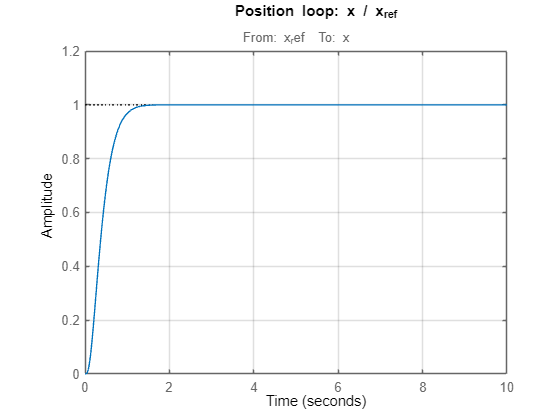

%% Step responses
T_pos   = getIOTransfer(CLtuned,'x_ref','x');
T_rate  = getLoopTransfer(CLtuned,'e_w',-1);   % w/w_ref internal
T_angle = getLoopTransfer(CLtuned,'e_phi',-1); % phi/phi_ref internal
T_vel   = getLoopTransfer(CLtuned,'e_v',-1);   % v/v_ref internal

figure; step(T_pos,10); grid on; title('Position loop: x / x_{ref}')

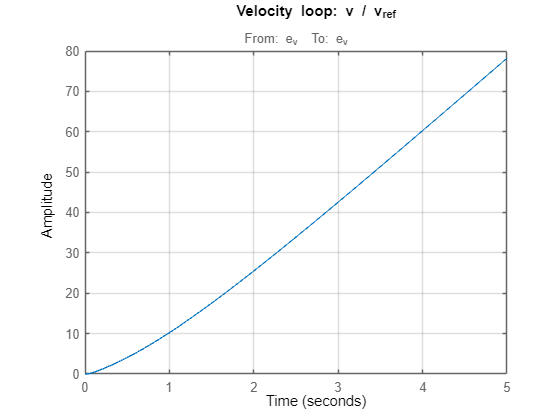

figure; step(T_vel,5); grid on;  title('Velocity loop: v / v_{ref}')

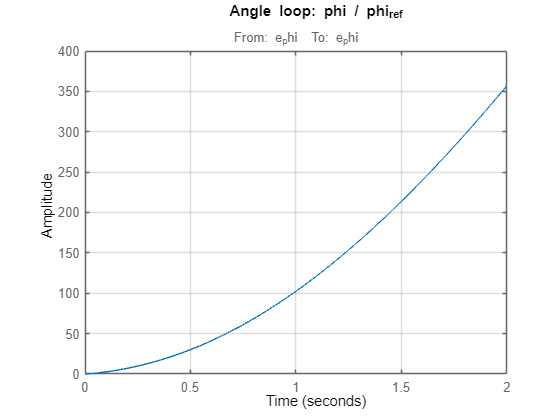

figure; step(T_angle,2); grid on;title('Angle loop: phi / phi_{ref}')

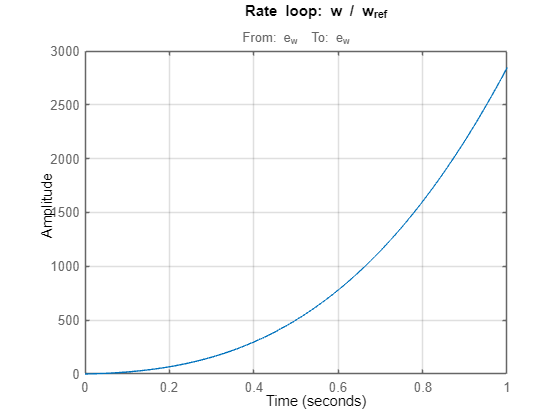

figure; step(T_rate,1); grid on; title('Rate loop: w / w_{ref}')

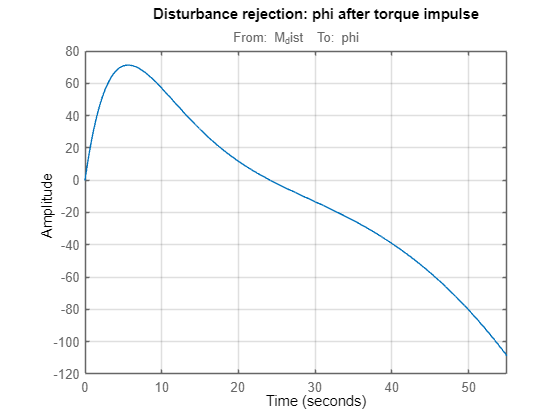

%% Disturbance rejection (torque -> phi)
CLd = connect(C_pos,C_vel,C_angle,C_rate, ...
              G_x,G_vphi,G_phi,G_inner, ...
              Sum_x,Sum_v,Sum_phi,Sum_w,Sum_M, ...
              {'x_ref','M_dist'}, {'phi','w'});

T_phi_dist = getIOTransfer(CLd,'M_dist','phi');
figure; impulse(T_phi_dist,55); grid on
title('Disturbance rejection: phi after torque impulse')